%---------------------- Exercise 2 --------------------%

% Task 1

t = 1790:10:2000; % date t in years
P = 197273000./(1+exp(-0.03134 *((t-1913.25)')));
format long
T = table( t', P, 'VariableNames', { 'Time','Population'});
disp('Population Modeled to time in years are: ');

Population Modeled to time in years are: 


disp(T);

    Time       Population   
    ____    ________________

    1790    4059821.99313699
    1800    5512360.45010349
    1810    7464515.94162672
    1820    10071699.9781082
    1830    13524627.4766601
    1840    18047215.0074285
    1850    23885550.2547929
    1860    31282940.1583398
    1870    40437014.9803248
    1880    51439659.7177905
    1890    64210378.4674735
    1900     78446149.497374
    1910    93617527.9819427
    1920    109030794.904286
    1930    123947285.537936
    1940     137719544.08244
    1950    149893845.737421
    1960    160248473.542148
    1970    168770426.819204
    1980    175596210.097514
    1990    180945498.829501
    2000    185066481.412342



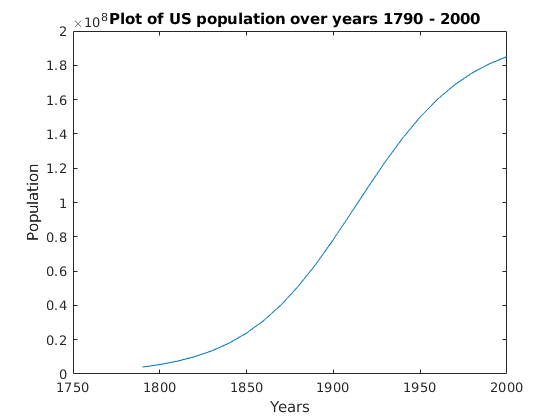

plot(t, P),
title('  Plot of US population over years 1790 - 2000');
xlabel('Years');
ylabel('Population');

if length(P) == length(unique(P))
    disp("Population doesn't reach to a steady state.")
else
    disp("Population reaches to a steady state.")
end

Population doesn't reach to a steady state.



% Task 2

fahrenheit = 56;
celcius = fahrenheit_to_celcius(fahrenheit);
disp([num2str(fahrenheit),' Fahrenheit Temperature is equal to ',num2str(celcius), ' Celsius Temperature']);

56 Fahrenheit Temperature is equal to 13.3333 Celsius Temperature


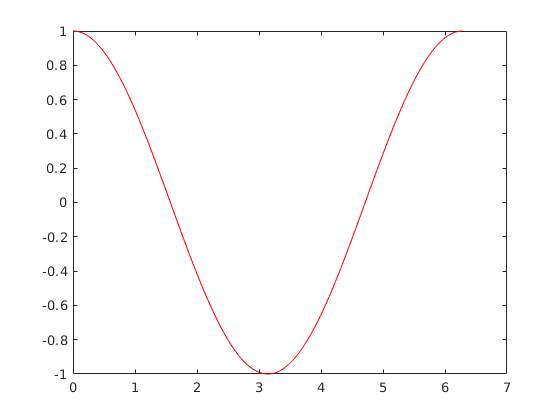


% Task 3

x = 0:0.01:(2*pi);
y = cos(x);
plot(x,y,'r-'); 

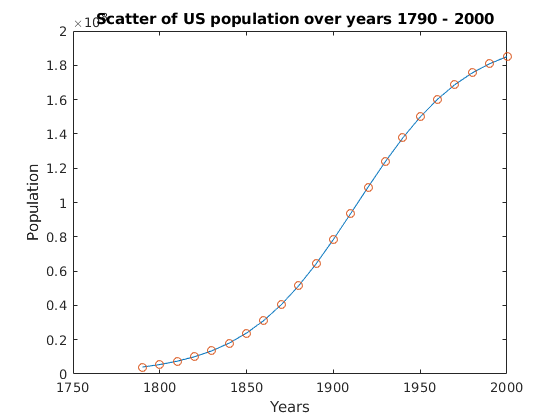

 
 % Task 4
 
t = 1790:10:2000; % date t in years
P = 197273000./(1+exp(-0.03134 *(t-1913.25)));
plot(t,P);
xlabel('Years');
ylabel('Population');
title('  Scatter of US population over years 1790 - 2000');
hold('on');
scatter(t, P),
hold('off')

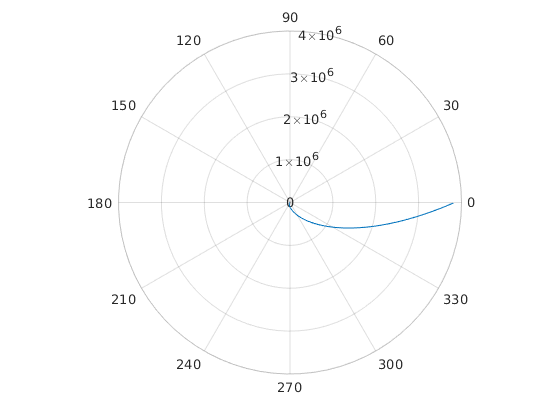


% Task 5

theta = 0:0.01:2*pi;
a=randi([1 10]); % choose arbitrary value of a > 0
q=randi([2 10]); % choose arbitrary value of q > 1
r = a * (q.^theta);
polarplot(theta,r)

function celcius = fahrenheit_to_celcius(fahrenheit)
    celcius = (5/9)*(fahrenheit-32);
end